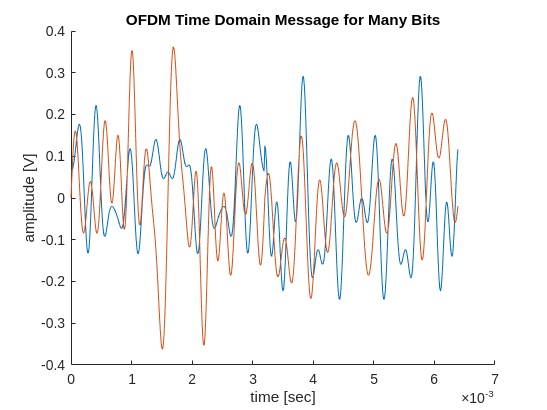

% Adam Nichols
% Prof. Jacobs
% ECE 1898
% 3 February 2025

% modulate/demodulate a message using a simple OFDM scheme

% reset the workspace
clear, clc

% generate a message of random bits
num_bits = 64;
bits = RandomBits(num_bits);

% parallelize bits into bitstreams
num_carriers = 32;
num_symbols = ceil(num_bits / num_carriers);
if mod(num_bits,num_carriers) > 0
    bits_padded = [bits; zeros(num_carriers-mod(num_bits,num_carriers),1)];
else
    bits_padded = bits;
end

data = reshape(bits_padded,num_carriers,[]);

% modulate OFDM symbols from the fourier coefficients
fourier_coeffs = data*2 - 1;
s_t = zeros(num_carriers,num_symbols);
% perform IFFT
for i = 0:num_symbols-1
    s_t(i*num_carriers+1:(i+1)*num_carriers) = ifft(fourier_coeffs(i*num_carriers+1:(i+1)*num_carriers));
end

% define timing parameters of the OFDM signal
bandwidth = 1e4;
guard_carriers = 4;
baseband_bandwidth = bandwidth/2+guard_carriers*bandwidth/num_carriers;
samplerate = bandwidth;
sampleperiod = 1/samplerate;
symboltime = sampleperiod * num_carriers;
symbolrate = 1/symboltime;
t = transpose((0:num_carriers*num_symbols-1)*sampleperiod);

% perform upsampling
upsamp = 8;
s_t_upsamp = zeros(num_carriers*upsamp,num_symbols);
for i = 0:num_symbols-1
    s_t_curr = s_t(i*num_carriers+1:(i+1)*num_carriers);
    if num_symbols > 1
        s_t_curr = transpose(s_t_curr);
    end
    s_t_curr_triple = [s_t_curr; s_t_curr; s_t_curr];
    s_t_curr_triple_upsamp = resample(s_t_curr_triple,upsamp,1);
    s_t_curr_upsamp = s_t_curr_triple_upsamp(upsamp*num_carriers+1:2*upsamp*num_carriers);
    s_t_upsamp((i*num_carriers*upsamp+1:(i+1)*num_carriers*upsamp)) = s_t_curr_upsamp;
end
samplerate_upsamp = upsamp*samplerate;
sampleperiod_upsamp = sampleperiod/upsamp;
t_upsamp = transpose((0:num_carriers*num_symbols*upsamp-1)*sampleperiod_upsamp);

% concatenate all OFDM symbols without guard intervals or filtering
s_t_upsamp_vec = reshape(s_t_upsamp,[],1);

% plot this upsampled, concatenated version of OFDM
figure(1)
clf
hold on
plot(t_upsamp,real(s_t_upsamp_vec))
plot(t_upsamp,imag(s_t_upsamp_vec))
title("OFDM Time Domain Message for Many Bits")
xlabel("time [sec]")
ylabel("amplitude [V]")

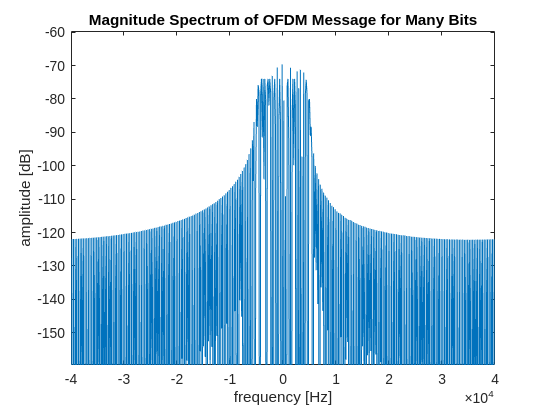


% get the spectrum of the concatednated signal
[f_upsamp_all, spec_upsamp_all] = GetSpectrum(s_t_upsamp_vec,samplerate_upsamp);
mag_spec_upsamp_all = 20*log10(abs(spec_upsamp_all));

% plot the spectrum of the upsampled signal
figure(2)
clf
plot(f_upsamp_all,mag_spec_upsamp_all)
title("Magnitude Spectrum of OFDM Message for Many Bits")
xlabel("frequency [Hz]")
ylabel("amplitude [dB]")
ylim([max(mag_spec_upsamp_all)-90, max(mag_spec_upsamp_all)+10])

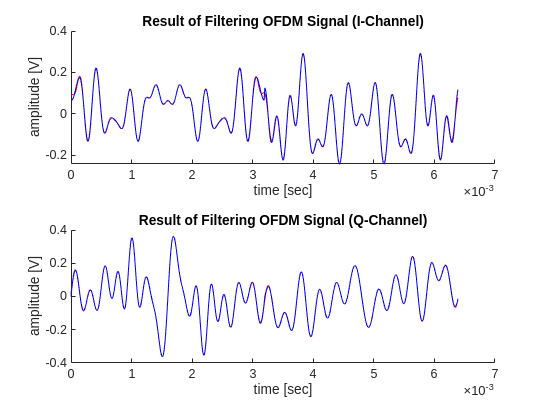


% pass the OFDM through a lowpass to meet channel specs
spec_lp = spec_upsamp_all;
spec_lp(abs(f_upsamp_all)>baseband_bandwidth) = 0;
mag_spec_lp = 20*log10(abs(spec_lp));

% perform ifft to get back time domain message
s_t_lp = ifft(ifftshift(samplerate_upsamp*spec_lp));

% plot the lowpassed version on same axes as original to show distortion
figure(3)
clf
tiledlayout
nexttile
hold on
plot(t_upsamp,real(s_t_lp),'r-')
plot(t_upsamp,real(s_t_upsamp_vec),'b-')
xlabel("time [sec]")
ylabel("amplitude [V]")
title("Result of Filtering OFDM Signal (I-Channel)")
nexttile
hold on
plot(t_upsamp,imag(s_t_lp),'r-')
plot(t_upsamp,imag(s_t_upsamp_vec),'b-')
xlabel("time [sec]")
ylabel("amplitude [V]")
title("Result of Filtering OFDM Signal (Q-Channel)")

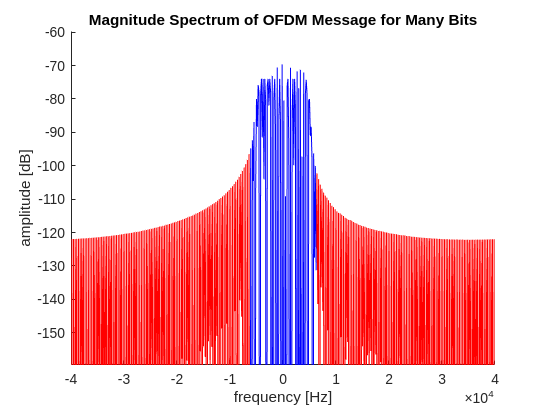


% plot the spectrum of the upsampled signal and the lowpassed version
figure(4)
clf
hold on
plot(f_upsamp_all,mag_spec_upsamp_all, 'r-')
plot(f_upsamp_all,mag_spec_lp, 'b-')
title("Magnitude Spectrum of OFDM Message for Many Bits")
xlabel("frequency [Hz]")
ylabel("amplitude [dB]")
ylim([max(mag_spec_upsamp_all)-90, max(mag_spec_upsamp_all)+10])

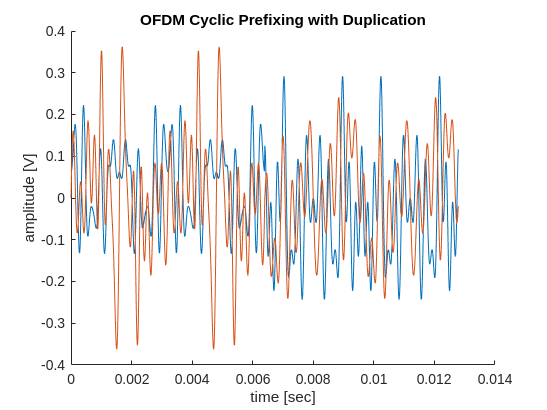


% perform cyclic prefixing to reduce spurious emission
% duplicate each symbol for a cyclic prefix, shorten later
t_prefix = transpose((0:num_carriers*num_symbols*upsamp*2-1)*sampleperiod_upsamp);
[s_t_upsamp_symbol_length, s_t_upsamp_num_symbols] = size(s_t_upsamp);
s_t_prefix = [];
for i = 1:num_symbols
    s_t_prefix = [s_t_prefix; s_t_upsamp(1:s_t_upsamp_symbol_length, i); s_t_upsamp(1:s_t_upsamp_symbol_length, i)];
end

% plot the prefix version of s(t)
figure()
clf
hold on
plot(t_prefix,real(s_t_prefix))
plot(t_prefix,imag(s_t_prefix))
title("OFDM Cyclic Prefixing with Duplication")
xlabel("time [sec]")
ylabel("amplitude [V]")

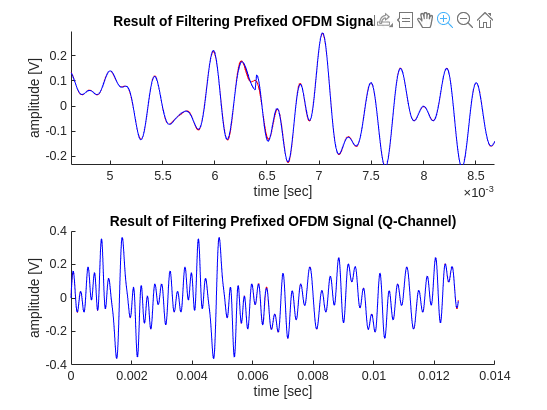


% get the spectrum of the prefixed version
[f_prefix, spec_prefix] = GetSpectrum(s_t_prefix,samplerate_upsamp);
mag_spec_prefix = 20*log10(abs(spec_prefix));

% pass this prefixed version through an ideal brick-wall lowpass filter
spec_prefix_lp = spec_prefix;
spec_prefix_lp(abs(f_prefix)>baseband_bandwidth) = 0;
mag_spec_prefix_lp = 20*log10(abs(spec_prefix_lp));

% perform ifft to get back time domain message
s_t_prefix_lp = ifft(ifftshift(samplerate_upsamp*spec_prefix_lp));

% plot the lowpassed version on same axes as original to show distortion
figure(5)
clf
tiledlayout
nexttile
hold on
plot(t_prefix,real(s_t_prefix_lp),'r-')
plot(t_prefix,real(s_t_prefix),'b-')
xlabel("time [sec]")
ylabel("amplitude [V]")
title("Result of Filtering Prefixed OFDM Signal (I-Channel)")
nexttile
hold on
plot(t_prefix,imag(s_t_prefix_lp),'r-')
plot(t_prefix,imag(s_t_prefix),'b-')
xlabel("time [sec]")
ylabel("amplitude [V]")
title("Result of Filtering Prefixed OFDM Signal (Q-Channel)")

## Functions:

% GetSpectrum gets the spectrum of the input signal
% uses the fftshift function to make DC appear at center term
function [f,spectrum] = GetSpectrum(samples, sample_rate)

    % determine the spectrum of the baseband signal
    spectrum = 1/sample_rate*fftshift(fft(samples));
    
    % get bin numbers (centered at 0)
    f_bins = (0:length(samples)-1) - floor(length(samples)/2);

    % define the frequency range
    f = transpose(f_bins * sample_rate / length(f_bins));
end

function bits = RandomBits(num_bits)
    % create a vector of random bits to the required length
    bits = zeros(num_bits,1);
    for i = 1:num_bits
        bits(i) = randi(2,1)-1;
    end
end